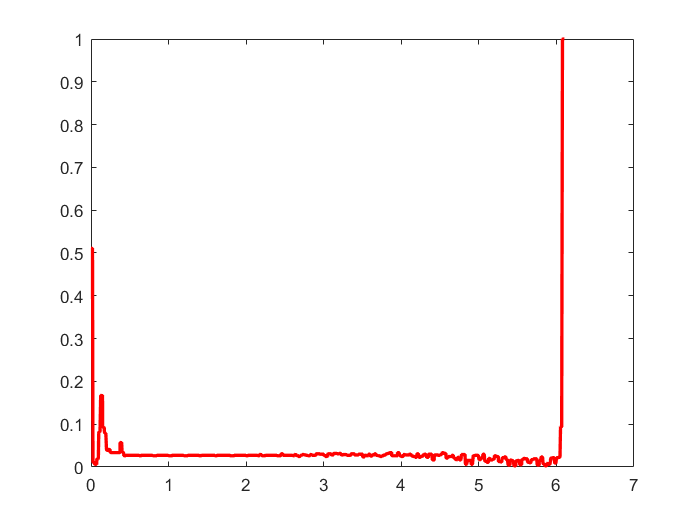

% read sound 
[data, fs] = audioread('DoorBell_2.wav');
% normalize data
data = data / abs(max(data));

% do framing
f_d = 0.025;
frames = framing(data, fs, f_d);
[r, c] = size(frames);

for i = 1 : r
    x = frames(i, :);
    ZCRf1(i) = sum(x(1 : end - 1) .* x(2:end) <= 0);
        
end

% calculating rate
ZCRr1 = ZCRf1/length(x);
ZCRr1 = ZCRr1/max(ZCRr1);

% ZCRr1 = ZCRf1;
f_size = round(f_d * fs);
zcr_wave = 0;
for j = 1 : length(ZCRr1)
    l = length(zcr_wave);
    zcr_wave(l : l + f_size) = ZCRr1(j);
end
% plot the ZCR with Signal
t = [0 : 1/fs : length(data)/fs]; % time in sec
t = t(1:end - 1);
t1 = [0 : 1/fs : length(zcr_wave)/fs];
t1 = t1(1:end - 1);
% data = data/10;
%plot(t,data'); hold on;
plot(t1,zcr_wave,'r','LineWidth',2);